fs=48000;
f0=18000;
N=8;

mode='pixel3';
fileFolder=fullfile(['receive/', mode]);
dirOutput=dir(fullfile(fileFolder,'*.pcm'));
fileNames={dirOutput.name};

file_name=fileNames{end}

file_name = '20220311161514.pcm'

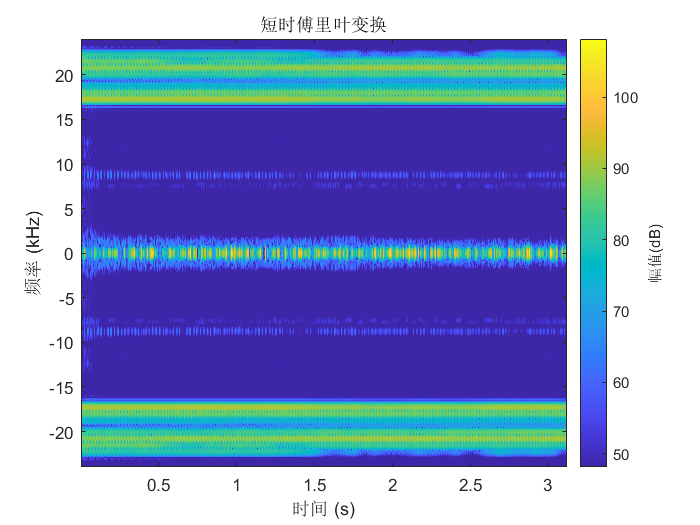

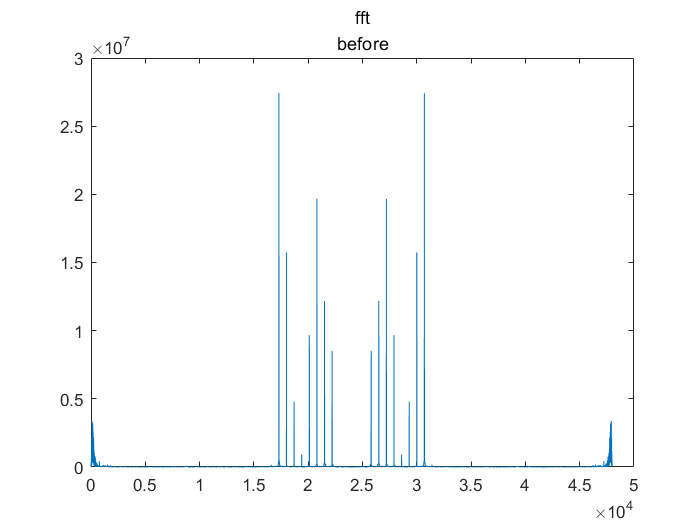

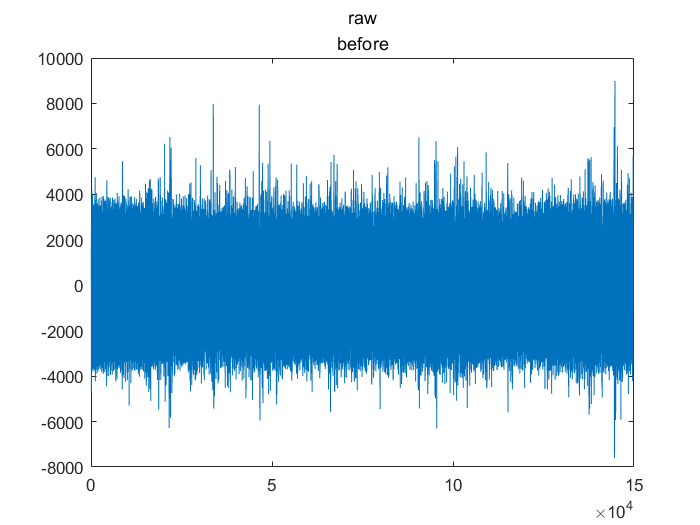

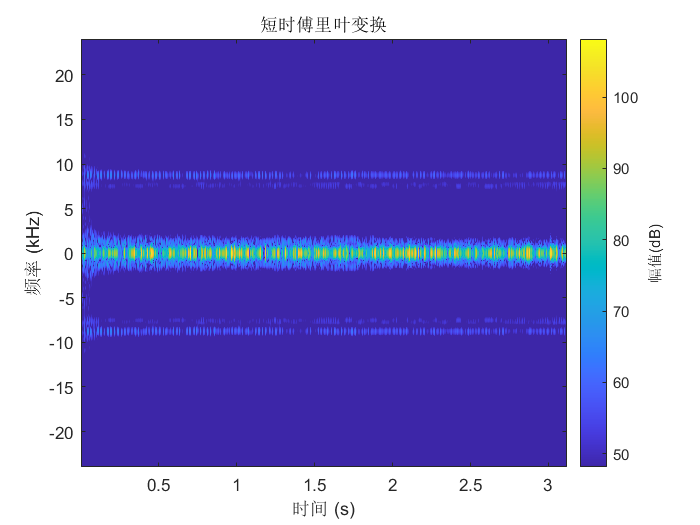

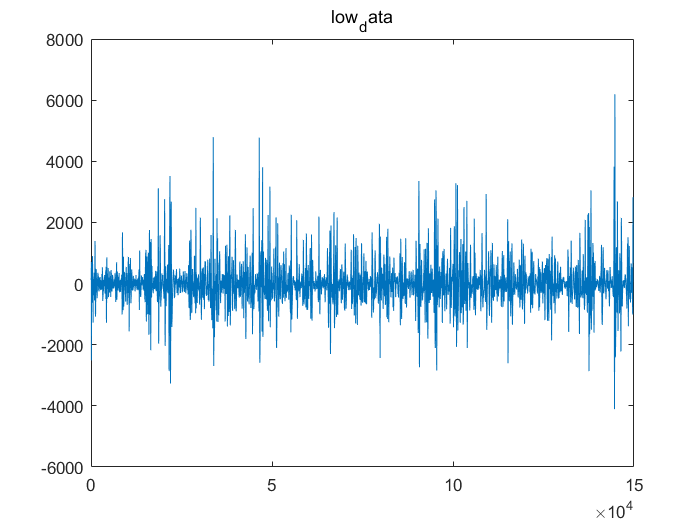

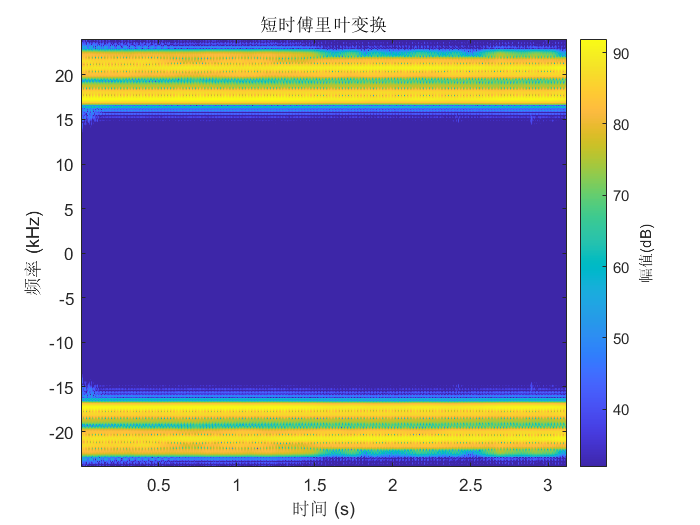

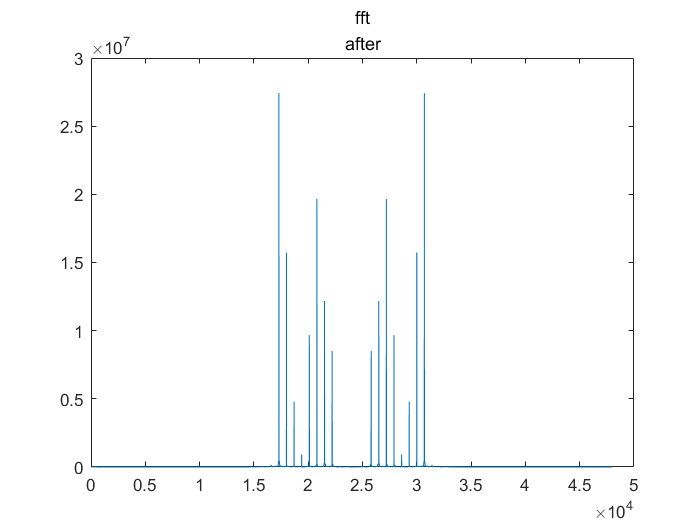

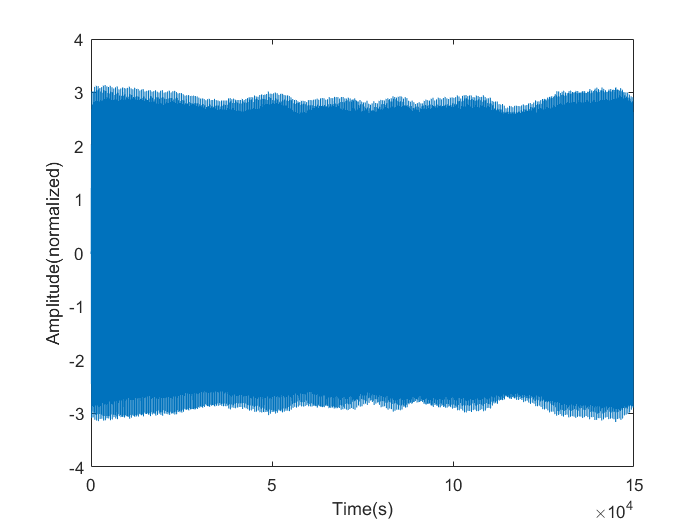


file=['receive/' , mode,'/', file_name];
data= importdata(file);
% snr(data);

low_data=lowpass(data, 8000, fs);

write_data=int16(data);
write_data=int16(low_data);
audiowrite("test.wav", write_data, fs);
test_data=importdata("test.wav").data;
sound(test_data, 48000, 16);




data=plot_highpass(data, fs);

ans = "----------------analysis_single-----------------"

time = 149760

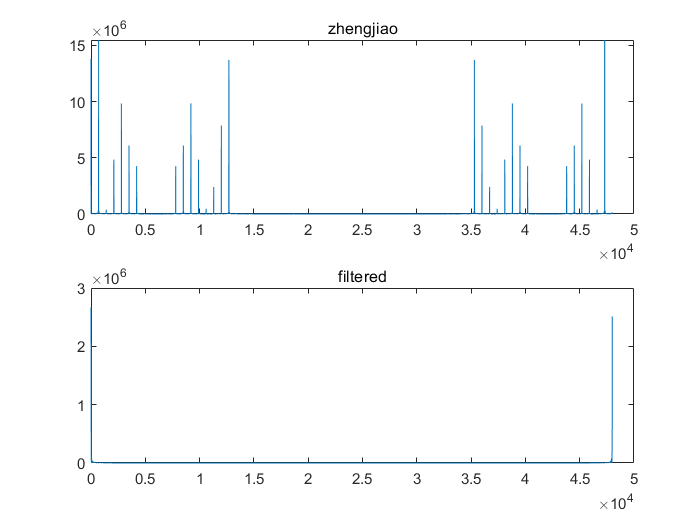

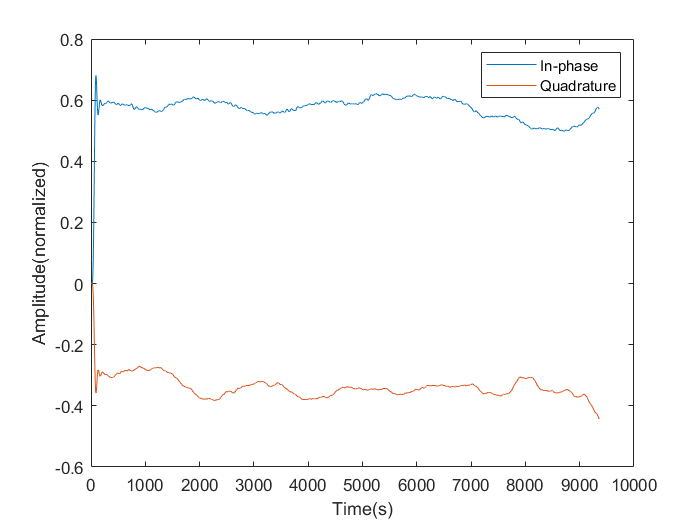

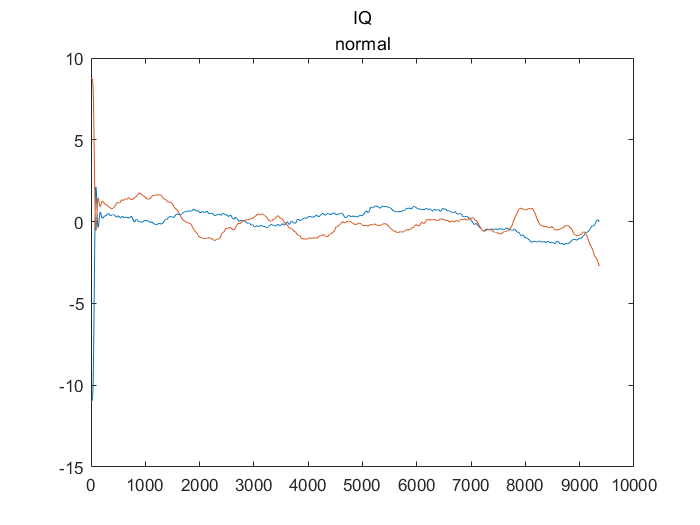

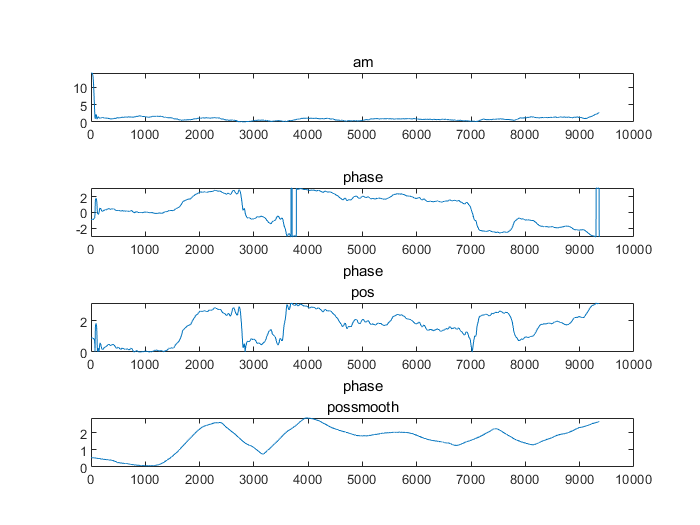

tot_phase = -8.4743

tot_dist = -1.2738

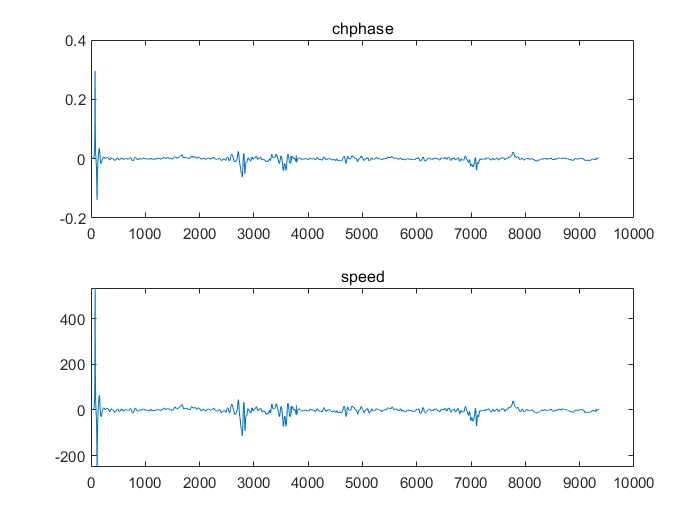

ans = "----------------plot_grad-----------------"

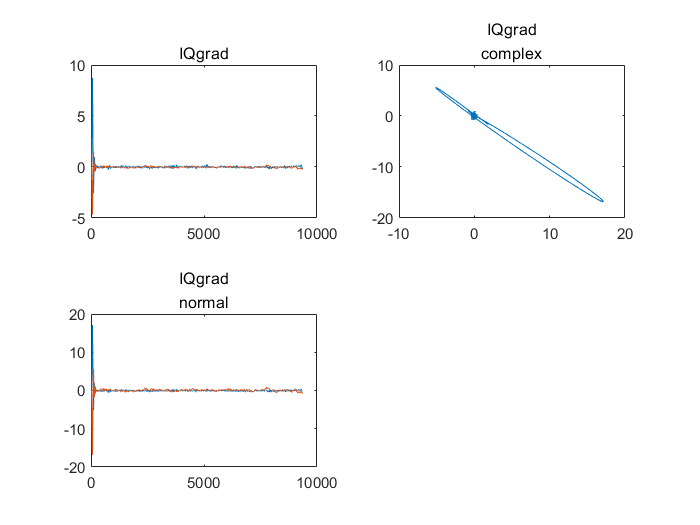

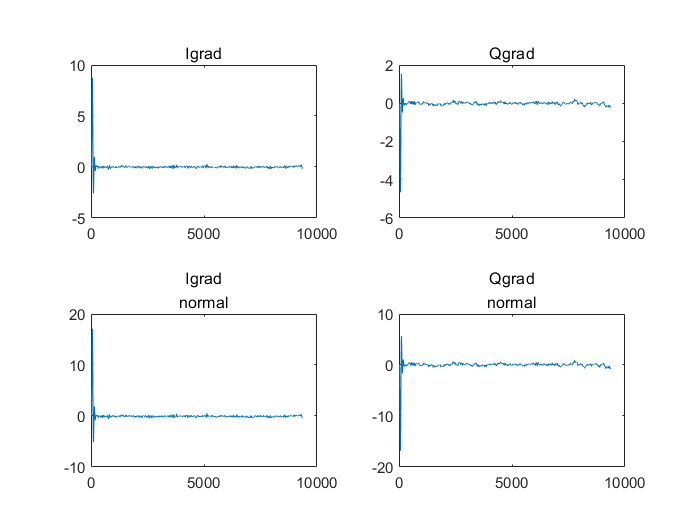

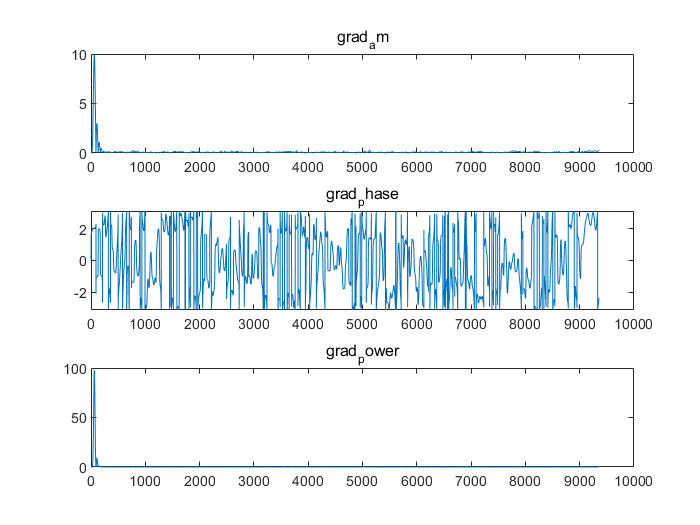

analysis_single(data, fs, f0);